%% Add_Stripe_Noise.m
% Adds synthetic vertical stripe noise to an image and saves it.

clc; clear; close all;

%Load Original Image
img_path = "C:\Users\Mahallakshmi\OneDrive\Documents\S3_projects\Mfc_S3\Image2.jpg";
img = imread(img_path);

% Convert to grayscale if RGB
if size(img,3) > 1
    img = rgb2gray(img);
end
O = im2double(img);


% Add Synthetic Stripe Noise
stripe_ratio = 0.4;      % 40% of columns affected
noise_intensity = 0.5;   % Noise level (-0.5 to 0.5)
stripes = zeros(size(O));
num_stripes = round(stripe_ratio * size(O,2));
stripe_cols = randperm(size(O,2), num_stripes);

for col = stripe_cols
    stripes(:,col) = randn() * noise_intensity;
end

O_striped = O + stripes;
O_striped = max(0, min(1, O_striped)); % Clip to [0,1]


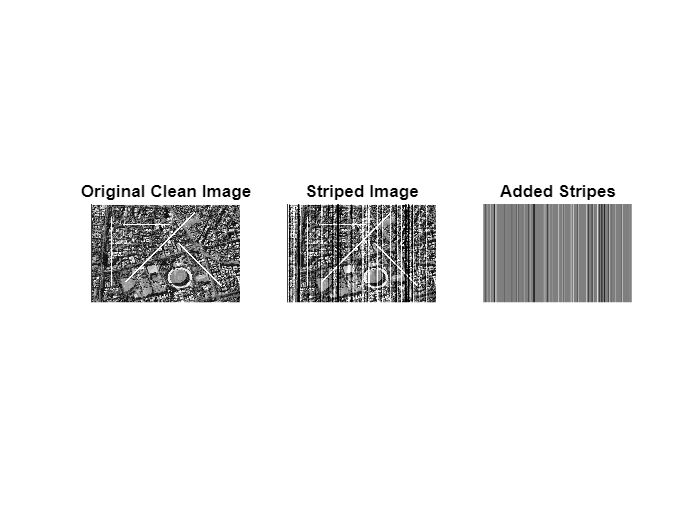

% Display & Save
figure;
subplot(1,3,1); imshow(O); title('Original Clean Image');
subplot(1,3,2); imshow(O_striped); title('Striped Image');
subplot(1,3,3); imshow(stripes, []); title('Added Stripes');

% Save Striped Image
output_path = "C:\Users\Mahallakshmi\OneDrive\Documents\S3_projects\Mfc_S3\Striped_Image.jpg";
imwrite(O_striped, output_path);

fprintf('Striped image saved at:\n%s\n', output_path);

Striped image saved at:
C:\Users\Mahallakshmi\OneDrive\Documents\S3_projects\Mfc_S3\Striped_Image.jpg
